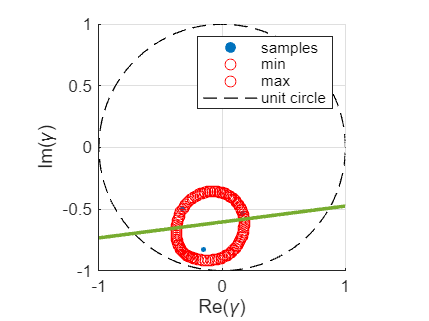

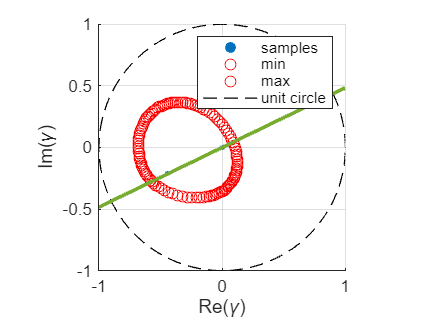

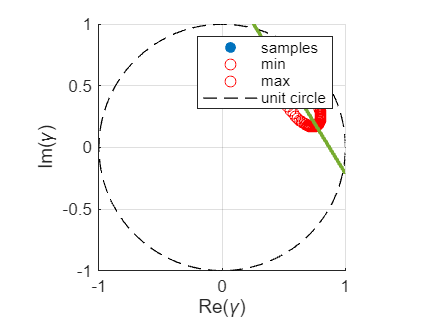

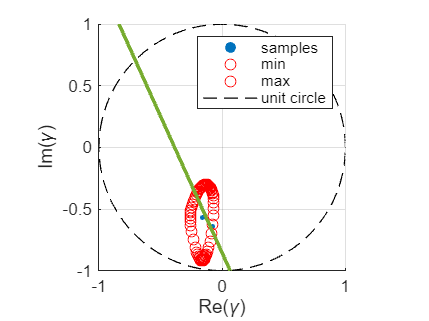

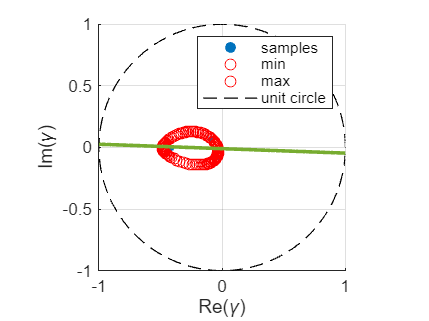

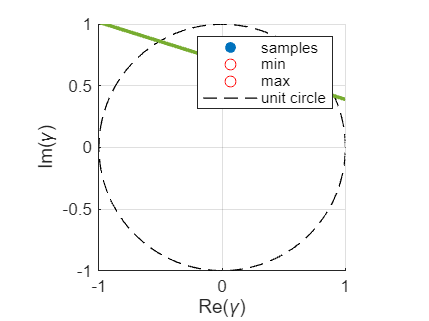

clear;

fileNames = ["data/c3x7_s1602_l48.m","data/c3x7_s1794_l290.m","data/c3x7_s1914_l275.m","data/c7x17_s1602_l48.m","data/c7x17_s1794_l290.m","data/c7x17_s1914_l275.m"];
P_values = zeros(6, 2);
for l=1:6
boundary_N = 60;
fileName = fileNames(l);
run(fileName);
CoherencePoints = PhaseDiversityFunc(fileName);
boundary_vals = BoundaryScan(fileName, boundary_N);

P = linortfit(real(CoherencePoints), imag(CoherencePoints));
P_values(l, :) = P;


% --- Plot the brute-force sampled points ---
figure('Name','Coherence points','NumberTitle','off');
hold on;  % keep all plots in the same figure
axis equal; grid on;

% scatter plot of your samples
scatter(real(CoherencePoints), imag(CoherencePoints), 8, 'filled');

scatter(real(boundary_vals(:,1)), imag(boundary_vals(:,1)), 'ro', 'red');
scatter(real(boundary_vals(:,2)), imag(boundary_vals(:,2)), 'ro', 'red');

% draw unit circle for reference
th = linspace(0,2*pi,500);
plot(cos(th), sin(th), 'k--', 'LineWidth', 0.7);
x = linspace(-1, 1, 100);
plot(x,P(1)+P(2)*x, 'LineWidth', 2);
% labels and title
xlabel('Re(\gamma)'); 
ylabel('Im(\gamma)');
xlim([-1 1]);
ylim([-1 1]);

% legend
legend('samples','min','max', 'unit circle');

hold off;  % optional, release hold

end


writematrix(P_values, "PhaseDiversity_OR_Values");
